clc, clear, close all

## Environment Properties

World.p = 1.225; 
World.grip_scale = 1;

## Load Track

Track = load("C:\Users\bjmyn\OneDrive - Virginia Tech\Documents\Formula SAE\4 - 2024 Spring\Lap Sim\Ben Version 1.0\skidpad.mat");
Track.RWP = abs(1./Track.KWP);
if Track.start_from_zero
    Track.RWP(1) = 0.01;
end
Track.RWP(~isfinite(Track.RWP)) = 10000;

## Load Cars

Paddock(1).car = Car4W("car_01.json",...
                       "power_01.json",...
                       World);

## Use Walking Algorithm on Each Car

for i = 1:length(Paddock)
    disp("Calculating cornering velocities for Car "+i+" ...")
    VWP = cornVel(Paddock(i).car,Track.SWP,Track.RWP);
    disp("Done calculating cornering velocities for Car "+i+" ...")
    
    Log(i).VWP = VWP;

    disp("Walking points for Car "+i+" ...")
    [Log(i).MVWP,Log(i).GX,Log(i).GY] = walk(Paddock(i).car,Track.SWP,VWP,Track.RWP);
    disp("Done walking points for Car "+i+" ...")
    
    Paddock(i).laptime = lapTime(Track.SWP,Log(i).MVWP);
    Paddock(i).MVWP = Log.MVWP;
    fprintf("Car "+i+" completed track in %3.3f seconds.\n",Paddock(i).laptime);
    fprintf("\n");
end

Calculating cornering velocities for Car 1 ...


Done calculating cornering velocities for Car 1 ...


Walking points for Car 1 ...


100/100


Done walking points for Car 1 ...


Car 1 completed track in 4.970 seconds.


## Plot Results

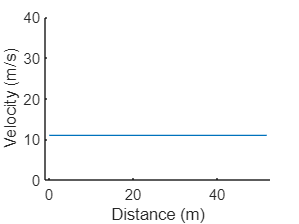

figure()
hold on
for i = 1:length(Paddock)
    plot(Track.SWP,Log(1).MVWP)
end
xlim([-1,Track.SWP(end)+1])
ylim([0,40])
xlabel("Distance (m)")
ylabel("Velocity (m/s)")

fprintf("Done!\n")

Done!


## [Functions] Walk Algorithm

function [MVWP,GX,GY] = walk(Car,SWP,VWP,RWP)
    % Initialize velocity vectors
    UWP = SWP.*0; 
    a = SWP.*0;
    MVWP = VWP.*0 + realmax;
    GX = MVWP;
    GY = MVWP;
    gear = MVWP.*0;
    RPM = MVWP.*0;
    

### "Walking" Algorithm:


$$a_x =\pm \sqrt{a_x^2 -{\left(C_{\textrm{ax}} a_y \right)}^2 }=\pm \sqrt{a_x^2 -{\left(C_{\textrm{ax}} \frac{{v_x }^2 }{R}\right)}^2 }$$


Throttle: $v_i =\sqrt{v_{i-1}^2 +2a_{\textrm{xi}} \Delta x}$

Brake: $v_i =\sqrt{v_{i+1}^2 -2a_{\mathrm{xi}} \Delta x}$

    for n = 1:length(SWP)
        % Set current waypoint velocity to max cornering velocity
        UWP(n) = VWP(n); 
        if VWP(n) < MVWP(n)
            % Walk forward from n
            for i = (n+1):length(SWP)
                dx = SWP(i) - SWP(i-1); % cur-last
                a(i) = real(sqrt(Car.axT_fcn(UWP(i-1)).^2 - (Car.ax_scale.*UWP(i-1).^2./RWP(i)).^2));
                UWP(i) = sqrt(UWP(i-1).^2 + 2.*a(i).*dx);
            end
            % Walk backward from n
            for i = 1:(n-1)
                j = n-i; % reverse i
                dx = SWP(j+1) - SWP(j); % next-cur
                a(j) = -real(sqrt(Car.axB_fcn(UWP(j+1)).^2 - (Car.ax_scale.*UWP(j+1).^2./RWP(j)).^2));
                UWP(j) = sqrt(UWP(j+1).^2 - 2.*a(j).*dx);
            end

            GX =   GX  .* (MVWP <= UWP)        +      a./9.8 .* (MVWP > UWP);
            GY =   GY  .* (MVWP <= UWP) + (UWP.^2./RWP)./9.8 .* (MVWP > UWP);
            MVWP = MVWP .* (MVWP <= UWP)       +         UWP .* (MVWP > UWP);
        end
        % Display point progress (optional)
        if ~(mod(n,100))
            fprintf(n+"/"+length(SWP)+"\n")
        end
    end
end

## [Functions] Corner Velocities

function VWP = cornVel(Car,SWP,RWP)
    VWP = SWP.*0;


### Determining Cornering Velocities:

Condition: $\frac{{v_x }^2 }{R}=a_y \left(v_x \right)$

    for i = 1:length(SWP)
        err = @(v) v.*abs(v) ./ RWP(i) - Car.ay_fcn(v);
        VWP(i) = fzero(err,0);
    end
end

## [Functions] Lap Time

function t = lapTime(SWP,VWP)
    VWP(1) = 1;
    t = trapz(SWP, 1./(VWP));
end